# **Elementry AI HW2 (Iris Question)**

**Clearing Command window and Workspace:**

close all;
clear;
clc;

**Fixing Random Number Generator (RNG):**

**{42 is just a contracted seed between programmers!}**

rng(42);

**Declaring Hyperparameters:**

**(Length of every chromosome is 4)**

half_Elitism = 0;
population = 20;
generations = 50;
mutation_rate = 0.1;
crossover_rate = 0.8;
tournament_amount = 3;
% Constants:
K = 3;
trains_amount = 105;   % (150 * 0.7)
tests_amount = 45;     % (150 * 0.3)

**History for plotting:**

best_fitness_history = zeros(1, generations);
mean_fitness_history = zeros(1, generations);

**Loading CSV File:**

One_Block = true;
Elitism = 2 * half_Elitism;
table_datas = readtable("iris.csv"); % table (150 * 5)
x = table2array(table_datas(:, 1:4));
y = zeros(150, 1);

for i = 1:150
    if strcmp(table_datas{i,5} , 'Iris-setosa')
        y(i) = 1;
    elseif strcmp(table_datas{i,5} , 'Iris-versicolor')
        y(i) = 2;
    elseif strcmp(table_datas{i,5} , 'Iris-virginica')
        y(i) = 3;
    end
end

**Normalizing x with this formula:**


$$x\longleftarrow \frac{x-\mu_x }{\sigma_x }$$


X_mean = mean(x, 1); % axis = 1
X_std = std(x, 0, 1); % flag = 0 , axis = 1
% update:
x = (x - X_mean) ./ X_std;
creatures = zeros(population, 4);
fitnesses = zeros(population, 1);

% initialization
for i = 1:population
    creatures(i,:) = Random_Chromosome();
end

**Separating both "Train" and "Test" parts:**

Trains = zeros(trains_amount, 4);      % size = (105 , 4)
Tests = zeros(tests_amount, 4);        % size = (45  , 4)
Y_Trains = zeros(trains_amount, 1);    % size = (105 , 1)
Y_Tests = zeros(tests_amount, 1);      % size = (45  , 1)

for i = 0:2
    Trains(35*i+1 : 35*i+35 , :) = x(50*i+1 : 50*i+35 , :);
    Tests(15*i+1 : 15*i+15, :) = x(50*i+36 : 50*i+50 , :);
    Y_Trains(35*i+1 : 35*i+35 , 1) = y(50*i+1 : 50*i+35 , 1);
    Y_Tests(15*i+1 : 15*i+15, 1) = y(50*i+36 : 50*i+50 , 1);
end

**Main Loop:**

for Gen = 1:generations
    % Copying
    chromosomes = creatures;
    % Evaluating all of the Fitnesses:
    fitnesses = Fitness(creatures, K, Trains, Y_Trains, Tests, Y_Tests);
    [fitnesses, idx] = sort(fitnesses, 'descend');
    % Elitism (2 Networks):
    chromosomes(1,:) = creatures(idx(1),:);
    chromosomes(2,:) = creatures(idx(2),:);
    % Performing Selections, Crossovers and Mutations (18 Networks):
    chromosomes = Selection_Crossover(chromosomes, idx, crossover_rate, tournament_amount, Elitism);
    chromosomes = MUTATION(chromosomes, mutation_rate, Elitism);
    % Validation and Correction
    chromosomes = Validate(chromosomes);
    % Pasting the changes
    creatures = chromosomes;
    % Saving history
    best_fitness_history(Gen) = max(fitnesses);
    mean_fitness_history(Gen) = mean(fitnesses);
end

**Plotting:**

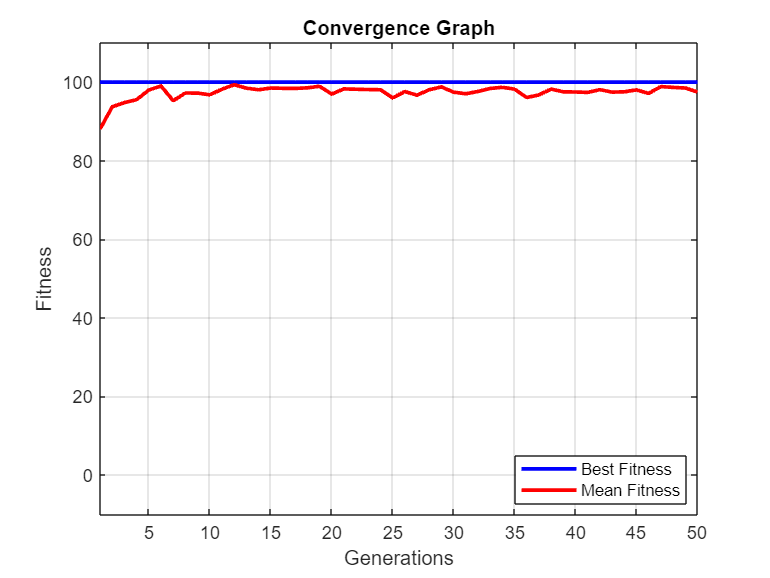

figure;
G = 1:generations;
plot(G, best_fitness_history, '-b', 'LineWidth', 2);
hold on;
plot(G, mean_fitness_history, '-r', 'LineWidth', 2);
title('Convergence Graph');
xlabel('Generations');
ylabel('Fitness');
legend('Best Fitness', 'Mean Fitness');
xlim([1,generations]);
ylim([-10,110]);
axis manual;
grid on;
% Declaring Legend for better demonstrations:
legend("Position", [0.67 , 0.13 , 0.22 , 0.08]);

if One_Block
    disp('Best Chromosome:');
    disp(creatures(1, :));
    disp(['Best Fitness (Train): ', num2str(best_fitness_history(end))]);
end

Best Chromosome:


     0     0     0     1



Best Fitness (Train): 100


# **Functions:**

**Function (1):**

function out = Random_Chromosome()
    out = randi([0 1], 1, 4);
    while all(out == 0)
        out = randi([0 1], 1, 4);
    end
end

**Function (2):**

function dis = Distance(Chr, M1, M2)
    dis = sqrt( sum(Chr .* (M1 - M2).^2) );
end

**Function (3):**

function predict = KNN(Chr, k, datas, labels, new_data)
    sz = size(datas, 1);
    DISTANCES = zeros(sz,1);
    for i = 1:sz
        DISTANCES(i) = Distance(Chr, datas(i,:), new_data);
    end
    [~ , idx] = sort(DISTANCES);
    lb = zeros(k,1);
    for i = 1:k
        N = idx(i);
        lb(i) = labels(N);
    end
    predict = mode(lb);
end

**Function (4):**

function F = Fitness(Chrs, k, datas, labels, Tests, Tests_labels)
    T_amount = size(Tests, 1);
    pop = size(Chrs, 1);
    F = zeros(pop, 1);

    for p = 1:pop
        for t = 1:T_amount
            tst = Tests(t, :);
            answer = Tests_labels(t);
            prd = KNN(Chrs(p,:), k, datas, labels, tst);

            if prd == answer
                F(p) = F(p) + 1;
            end
        end
        % Converting to Percent
        F(p) = (F(p) / T_amount) * 100;
    end
end


**Function (5):**

function RES = MUTATION(Chrs, Rate, Elite)
    pop = size(Chrs, 1);
    RES = Chrs;
    MUT = rand(pop - Elite, 4);
    binary_MUT = (MUT >= (1 - Rate));
    RES(Elite+1:pop , :) = xor(RES(Elite+1:pop , :) , binary_MUT);
end

**Function (6):**

function out = Validate(Chrs)
    pop = size(Chrs, 1);
    for i = 1:pop
        if all(Chrs(i,:)==0)
            r = randi([1,4]);
            Chrs(i,r) = 1;
        end
    end
    out = Chrs;
end

**Function (7):**

function [C1 , C2] = Cross_Over(P1, P2)
    cut_pose = randi([1,3]);
    C1 = zeros(1,4);
    C1(1:cut_pose) = P1(1:cut_pose);
    C1(cut_pose+1:end) = P2(cut_pose+1:end);
    C2 = zeros(1,4);
    C2(1:cut_pose) = P2(1:cut_pose);
    C2(cut_pose+1:end) = P1(cut_pose+1:end);
end

**Function (8):**

function out = Selection_Crossover(Chrs, index, CROSS_RATE, TOUR_AMNT, ELITE)
    pop = size(Chrs, 1);
    out = Chrs;
    counter = 3;
    c1 = zeros(1,4);
    c2 = zeros(1,4);
    repeating = (pop - ELITE) / 2;
    for i = 1:repeating
        attenders = randi([1,pop],TOUR_AMNT,1);
        attenders = sort(attenders, 'ascend');
        % Winners: attenders(1) & attenders(2)
        idx1 = index(attenders(1));
        idx2 = index(attenders(2));
        p1 = Chrs(idx1,:);
        p2 = Chrs(idx2,:);
        % Do we need Crossover or not?
        need = rand;
        if need < CROSS_RATE
            [c1 , c2] = Cross_Over(p1,p2);
        else
            c1 = p1;
            c2 = p2;
        end
        out(counter,:) = c1;
        counter = counter + 1;
        out(counter,:) = c2;
        counter = counter + 1;
    end
end